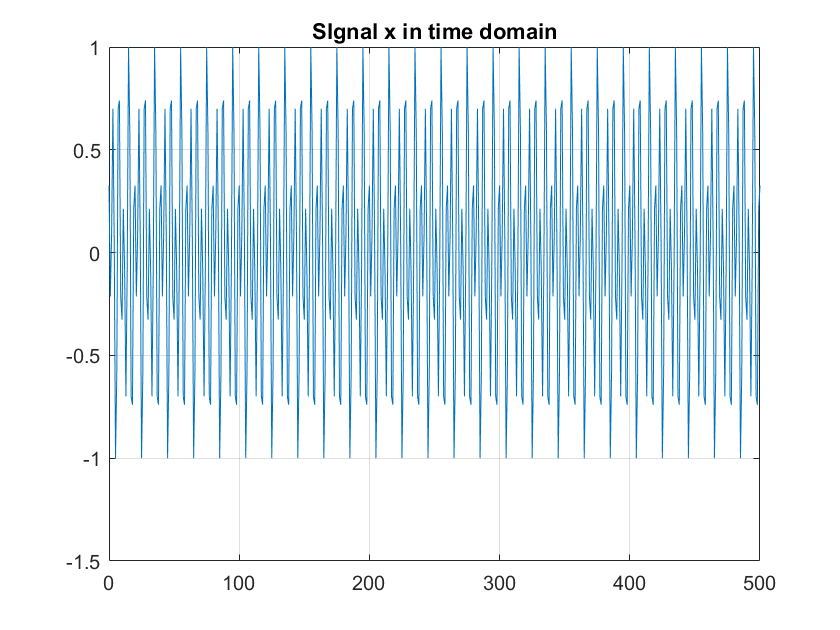

% prb 3.7
% For steady state response, number of samples in time domain and frequency
% domain must be same

n=500;
n=0:n; %since here used impulse function so indice array strats from 0
K=250;
% A=3
x=3*cos(0.5*pi*n+60*pi/180)+2*sin(0.3*pi*n);


% prb 3.3.1
h=0.9.^abs(n); 
% error=0.9299 highest error of response is in the system

% %prb 3.3.2
% [x1,n1]=unitseq(min(n),n(end),20);
% [x2,n2]=unitseq(min(n),n(end),-20);
% [xh,n]=sigadd(x1,n1,-x2,n2);
% h=(sinc(0.2*n).*xh);
% % error=0.8945

% %prb 3.3.3
% [x1,n1]=unitseq(min(n),n(end),0);
% [x2,n2]=unitseq(min(n),n(end),-40);
% [xh,n]=sigadd(x1,n1,-x2,n2);
% h=(sinc(0.2*n).*xh);
% % error=0.8923

% %prb 3.3.4
% h=(0.5.^n+0.4.^n).*unitseq(min(n),n(end),0);
% error=0.6162

% %prb 3.3.5
% h=0.5.^abs(n).*cos(0.1*pi*n);
% error=0.6172 lowest error of response is in the system

%DTFT of impulse response
[H,w]=dtft(h,n,K);

y=H.*x;
% [y,yn]=sigmult(H,w,x,n)

%plot 
figure("Name",'SIgnal x in time domain')
plot(n,real(x)/max(real(x)))
title('SIgnal x in time domain')
% xlim([-50 50])
grid on

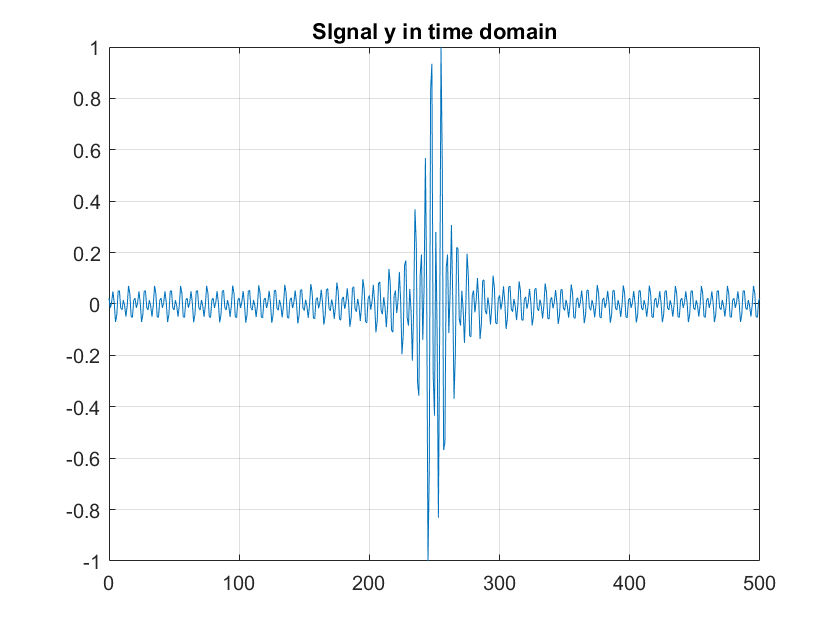


figure("Name",'SIgnal y in time domain')
plot(n,real(y)/max(real(y)))
% xlim([-50 50])
grid on
title('SIgnal y in time domain')


error=max(abs(real(y)/max(real(y))-real(x)/max(real(x))))

error = 0.9299

% error=max(abs(real(y)-real(x)))
